# Slice Plane Viewer Widget

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension in mm
    0 300 % X dimension in mm
    0 150 % Z dimension in mm
    ];

## Create the widget

f = uifigure;
g = uigridlayout(f,[1 1]);
w = wt.SlicePlaneViewer(g);
w.VolumeModel = volModel;

### Choose a slice

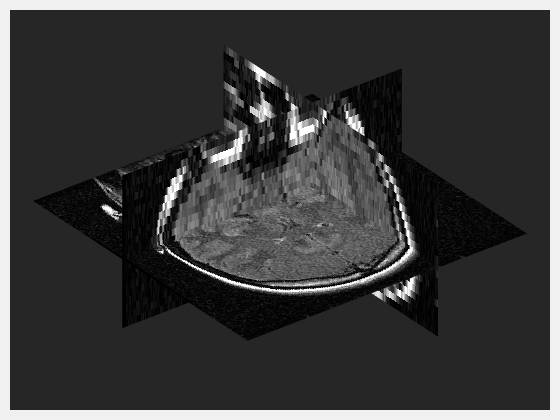

w.Slice = [150 175 10];

*Copyright 2018-2021 The MathWorks, Inc.*